Training

%% Define dataset path
dataFolder = 'C:\Users\Loren Ruth\BCD\dataset'; % Change path if needed

% Fix randomness for reproducibility
rng(69); % set random seed (same results every time)

% Load the dataset using ImageDatastore
imds = imageDatastore(dataFolder, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames'); % Use folder names as labels

disp('Class Labels:');

Class Labels:


disp(imds.Labels);

     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 


% Show count of images per class
tbl = countEachLabel(imds);
disp("Number of images per class:");

Number of images per class:


disp(tbl);

      Label       Count
    __________    _____

    cancer         120 
    non cancer     201 



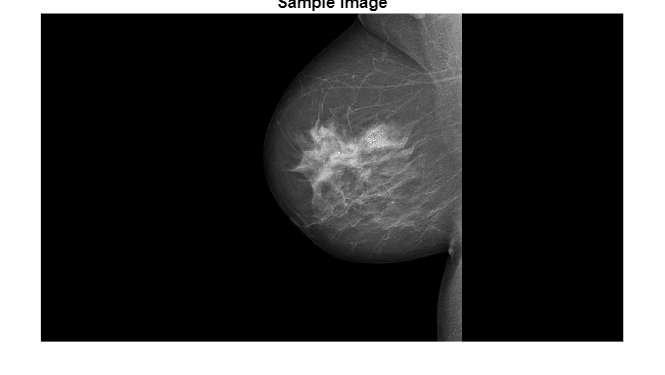


%% Function to convert grayscale → RGB
function rgbImage = convertGrayscaleToRGB(grayImage)
    if size(grayImage, 3) == 1
        rgbImage = repmat(grayImage, [1, 1, 3]); % Duplicate to make RGB
    else
        rgbImage = grayImage;
    end
end

% Test on first image
img = readimage(imds, 1);
if size(img,3) == 1
    img = convertGrayscaleToRGB(img);
end
figure; imshow(img); title('Sample Image');

%% Split into Training/Validation (60-40)
[trainImgs, valImgs] = splitEachLabel(imds, 0.6, 'randomized');

%% Data Augmentation
augmenter = imageDataAugmenter( ...
    'RandXTranslation', [-10, 10], ...
    'RandYTranslation', [-10, 10], ...
    'RandRotation', [-10, 10], ...
    'RandXReflection', true, ...
    'RandScale', [0.8, 1.2]);

augmentedTrainData = augmentedImageDatastore([224 224 3], trainImgs, 'DataAugmentation', augmenter);
augmentedValData   = augmentedImageDatastore([224 224 3], valImgs);

%% Load ResNet-50 and modify layers
net_res = resnet50;
lgraph = layerGraph(net_res);

numClasses = numel(categories(imds.Labels));

% Replace last fully connected layer
newFC = fullyConnectedLayer(numClasses, 'Name','fcNew', ...
    'WeightLearnRateFactor',10, 'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,'fc1000',newFC);

% Replace softmax layer
newSoftmax = softmaxLayer('Name','softmax');
lgraph = replaceLayer(lgraph,'fc1000_softmax',newSoftmax);

% Replace classification layer
newClassLayer = classificationLayer('Name','classOutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |       62.50% |       67.19% |       0.7799 |       0.6073 |      1.0000e-04 |
|       3 |          30 |       00:00:46 |      100.00% |       90.62% |       0.0339 |       0.3258 |      1.0000e-04 |
|       5 |          50 |       00:01:05 |       93.75% |              |       0.1201 |              |      1.0000e-04 |
|       5 |          60 |       00:01:17 |      100.00% |       92.19% |       0.0401 |   

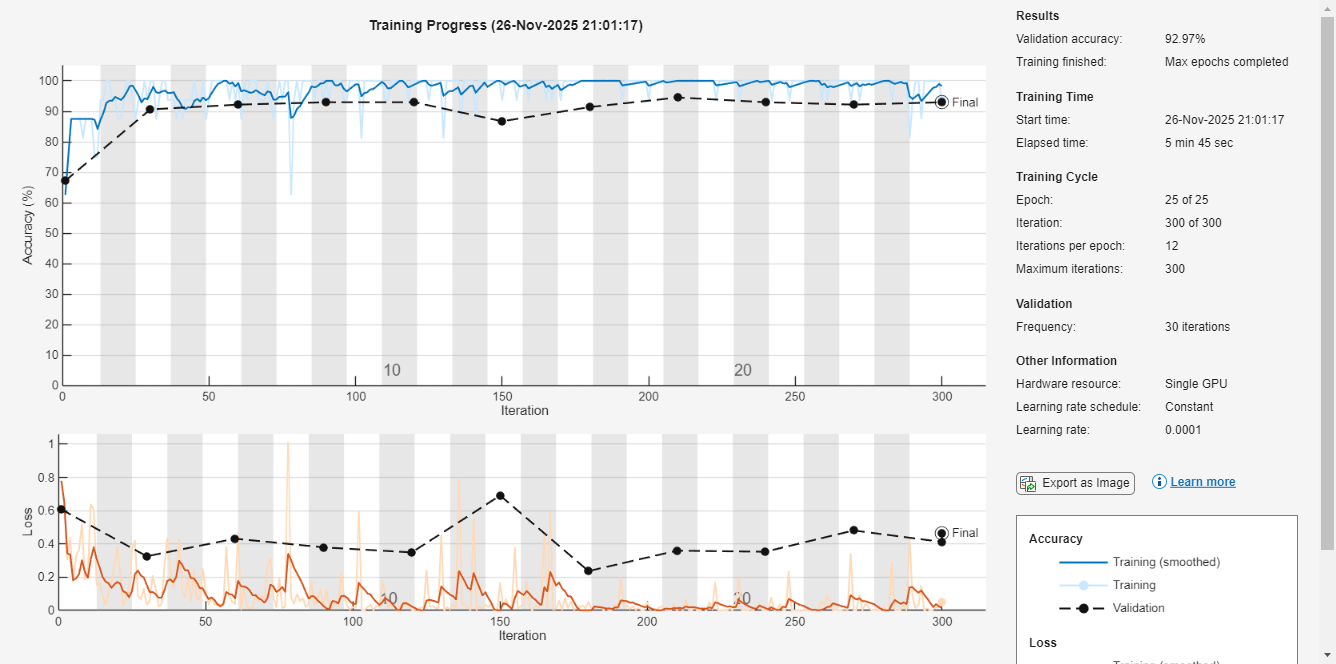

%% Training Options
options = trainingOptions('adam', ...
    'InitialLearnRate',1e-4, ...
    'MaxEpochs',25, ...  
    'MiniBatchSize',16, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augmentedValData, ...
    'ValidationFrequency',30, ...
    'Verbose',true, ...
    'Plots','training-progress');

%% Train the network
trainedNet = trainNetwork(augmentedTrainData, lgraph, options);

save('trainedResnet50.mat','trainedNet')

%% Evaluate Performance
YPred = classify(trainedNet, augmentedValData);
YValidation = valImgs.Labels;

% Validation Accuracy
accuracy = mean(YPred == YValidation);
fprintf("Validation Accuracy: %.2f%%\n", accuracy*100);

Validation Accuracy: 92.97%


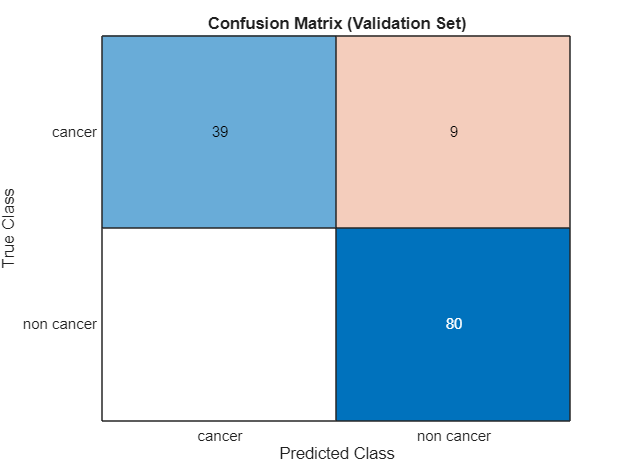


%% Confusion Matrix 
figure;
cmChart = confusionchart(YValidation, YPred, ...
    'Title','Confusion Matrix (Validation Set)', ...
    'RowSummary','off', ...
    'ColumnSummary','off');
cmChart.XLabel = 'Predicted Class';
cmChart.YLabel = 'True Class';


%% Metrics: Precision, Recall, F1-score
confMat = confusionmat(YValidation, YPred);

precision = diag(confMat) ./ sum(confMat,2);   % TP / (TP+FP)
recall    = diag(confMat) ./ sum(confMat,1)';  % TP / (TP+FN)
f1score   = 2 * (precision .* recall) ./ (precision + recall);

classNames = categories(YValidation);
numClasses = numel(classNames);

for i = 1:numClasses
    fprintf("Class: %s | Precision: %.2f | Recall: %.2f | F1-Score: %.2f\n", ...
        string(classNames(i)), precision(i)*100, recall(i)*100, f1score(i)*100);
end

Class: cancer | Precision: 81.25 | Recall: 100.00 | F1-Score: 89.66
Class: non cancer | Precision: 100.00 | Recall: 89.89 | F1-Score: 94.67


Testing

% Path to your test folder
testFolder = 'C:\Users\Loren Ruth\Downloads\datatest';

% Get list of all test images
testFiles = dir(fullfile(testFolder, '*.jpg'));

for k = 1:numel(testFiles)
    % Read image
    imgPath = fullfile(testFolder, testFiles(k).name);
    testImg = imread(imgPath);

    % Convert grayscale to RGB if needed
    if size(testImg,3) == 1
        testImg = repmat(testImg,[1 1 3]);
    end

    % Resize to match network input
    testImgResized = imresize(testImg, [224 224]);

    % Predict using trained network
    predictedLabel = classify(trainedNet, testImgResized);

    % Show image
    figure;
    imshow(testImg);
    title(['File: ', testFiles(k).name, newline, ...
           'Predicted: ', char(predictedLabel)]);
    
    % Print in command window
    disp(['File: ', testFiles(k).name, ...
          ' | Predicted Class: ', char(predictedLabel)]);
end